Stabilità

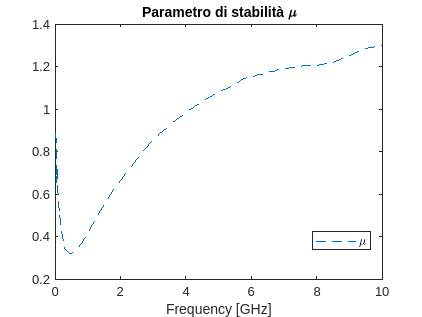

clear
clf

q_point = [8e-3 3]; %Ic VCE
op_freq = 1.6e9;
lin_freq = 3e7:10e6:5e9;

Z0=50; %ohm

bfp640 = read(rfckt.amplifier , ['BFP640/BFP640_w_noise_VCE_3.0V_IC_8.0mA.s2p']);
[s_par , freq] = extract(bfp640 , 'S_parameters');

[mu,muprime] = stabilitymu(s_par);
figure
plot(freq/1e9,mu,'--')
legend('\mu','Location','Best') 
title("Parametro di stabilità \mu")
xlabel('Frequency [GHz]')

gammas =0.3020*exp(-122.8*2*pi*i/360)

gammas = -0.1636 - 0.2539i

gammal =0.3993*exp(33.3*2*pi*i/360)

gammal = 0.3337 + 0.2192i

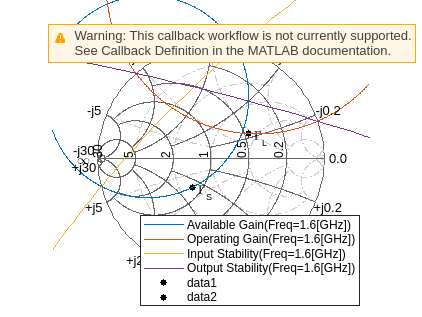


figure
sp = smithplot;
sp.GridType = 'YZ';
circle(bfp640 , op_freq , "Ga" , 22 , 'Gp' , 25 , 'Stab' , 'In' , 'Stab' , 'Out' , sp);
hold on
plot(gammas,'k.','MarkerSize',16);
text(real(gammas)+0.05,imag(gammas)-0.05,'\Gamma_{S}','FontSize', 12, ...
    'FontUnits','normalized');
plot(gammal,'k.','MarkerSize',16);
text(real(gammal)+0.05,imag(gammal)-0.05,['\Gamma_{L}'],'FontSize', 12, ...
    'FontUnits','normalized');
legend('Location','SouthEast')
hold off

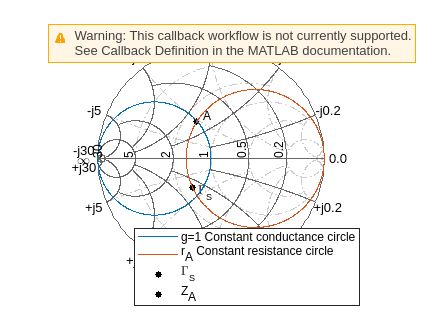


figure
sp1 = smithplot;
sp1.GridType = 'YZ';

Za = (0.641+0.474j)*Z0;

circle(bfp640 , op_freq , "G" , 1 , 'R' , real(gamma2z(gammas , 1)) , sp1);
hold on
plot(gammas,'k.','MarkerSize',16);
text(real(gammas)+0.05,imag(gammas)-0.05,'\Gamma_{S}','FontSize', 12, ...
    'FontUnits','normalized');

plot(z2gamma(Za),'k.','MarkerSize',16);
text(real(z2gamma(Za))+0.05,imag(z2gamma(Za))+0.05,'A','FontSize', 12, ...
    'FontUnits','normalized');
legend('g=1 Constant conductance circle' , 'r_A Constant resistance circle' , '\Gamma_{S}' , 'Z_A' , 'Location','SouthEast')
title('Smith Chart Input Matching')
hold off

imag(Za)

ans = 23.7000

C_shunt = 1/(abs(imag(1/Za))*2*pi*op_freq)

C_shunt = 6.6688e-09

C_series = 1/(abs(imag(gamma2z(gammas) - Za))*2*pi*op_freq)

C_series = 2.3913e-12




input_match = rfckt.cascade('Ckts', ...
    {rfckt.shuntrlc('L',C_shunt),rfckt.seriesrlc('C',C_series)});

Output match




figure
sp2 = smithplot;
sp2.GridType = 'YZ';


Zb = (1+1.083j)*Z0

Zb = 50.0000 + 54.1500i

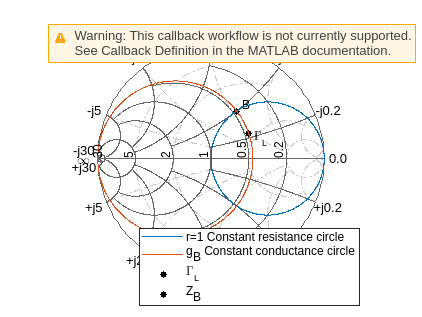


circle(bfp640 , op_freq , "R" , 1 , "G" , real(1/gamma2z(gammal , 1)) , sp2);
title('Smith Chart Output Matching')
hold on
plot(gammal,'k.','MarkerSize',16);
text(real(gammal)+0.05,imag(gammal)-0.05,['\Gamma_{L}'],'FontSize', 12, ...
    'FontUnits','normalized');

plot(z2gamma(Zb),'k.','MarkerSize',16);
text(real(z2gamma(Zb))+0.05,imag(z2gamma(Zb))+0.05,'B','FontSize', 12, ...
    'FontUnits','normalized');
legend('r=1 Constant resistance circle' , 'g_B Constant conductance circle' , '\Gamma_{L}' , 'Z_B' , 'Location','SouthEast')

hold off

imag(gamma2z(gammal,1) - Zb/50);
L_shunt = abs(imag(1/gamma2z(gammal,1) - 50/Zb))/(Z0*2*pi*op_freq)

L_shunt = 5.1411e-13

L_series = abs(imag(Zb))/(2*pi*op_freq)

L_series = 5.3864e-09




output_match = rfckt.cascade('Ckts', ...
  {rfckt.shuntrlc('C',L_shunt),rfckt.seriesrlc('L',L_series)});

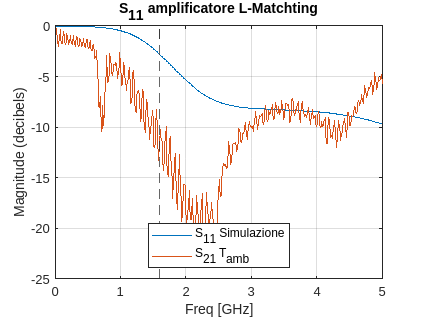

LNA = rfckt.cascade('ckts', ...
    {input_match,bfp640,output_match});

analyze(LNA,lin_freq);

LNA_sper = read(rfckt.amplifier , 'data/LNA_L/LNA_L_6V_TAMB_FIELDFOX.s2p');
analyze(LNA_sper,lin_freq);


LNA_sper_77K = read(rfckt.amplifier , 'data/LNA_L/LNA_L_6V_T077_FIELDFOX.s2p');
analyze(LNA_sper_77K,lin_freq);

cavi = read(rfckt.amplifier , 'data/CAVI_TAMB.s2p');
analyze(cavi,lin_freq);


figure,plot(LNA,'S11','dB');
title("S_{11} amplificatore L-Matchting")
hold on
plot(LNA_sper,'S11','dB');
xline(1.6 , "LineWidth", 1 , "LineStyle","--")
legend("S_{11} Simulazione" , "S_{21} T_{amb}" , "Location" , "south")
hold off

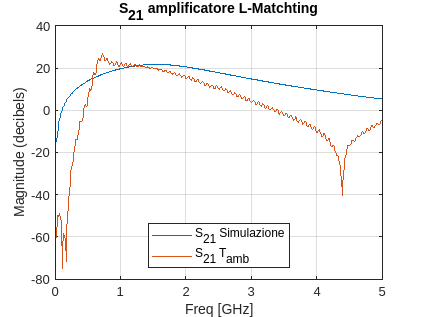


figure,plot(LNA,'S21','dB');
title("S_{21} amplificatore L-Matchting")
hold on
plot(LNA_sper,'S21','dB');

legend("S_{21} Simulazione" , "S_{21} T_{amb}" , "Location" , "south")
hold off

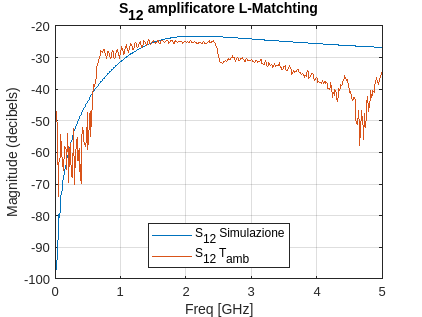


figure,plot(LNA,'S12','dB');
title("S_{12} amplificatore L-Matchting")
hold on
plot(LNA_sper,'S12','dB');
legend("S_{12} Simulazione" , "S_{12} T_{amb}" , "Location" , "south")
hold off

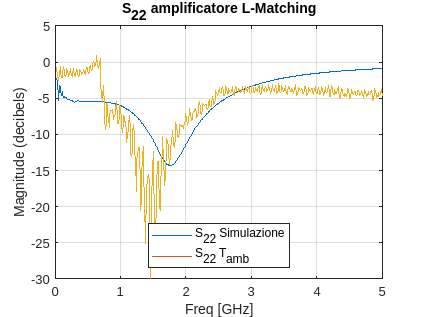


figure,plot(LNA,'S22','dB');
title("S_{22} amplificatore L-Matching")
hold on
plot(LNA_sper,'S22','dB');
plot(LNA_sper,'S22','dB');
legend("S_{22} Simulazione" , "S_{22} T_{amb}" , "Location" , "south")
hold off

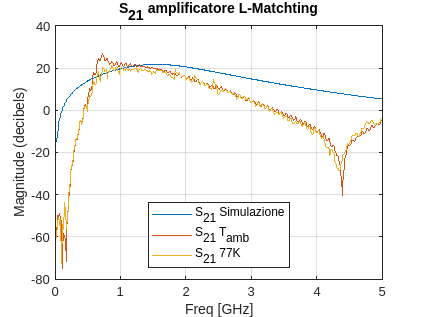


figure,plot(LNA,'S21','dB');
title("S_{21} amplificatore L-Matchting")
hold on
plot(LNA_sper,'S21','dB');
plot(LNA_sper_77K,'S21','dB');
legend("S_{21} Simulazione" , "S_{21} T_{amb}" , "S_{21} 77K" , "Location" , "south")
hold off

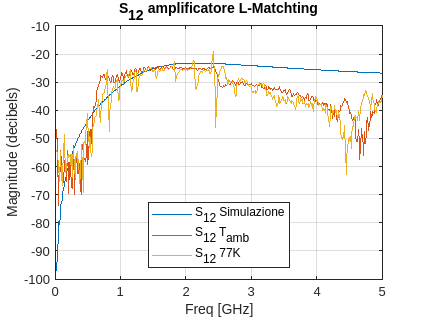


figure,plot(LNA,'S12','dB');
title("S_{12} amplificatore L-Matchting")
hold on
plot(LNA_sper,'S12','dB');
plot(LNA_sper_77K,'S12','dB');
legend("S_{12} Simulazione" , "S_{12} T_{amb}" , "S_{12} 77K" , "Location" , "south")
hold off

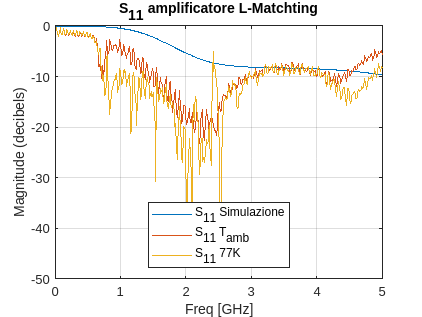



figure,plot(LNA,'S11','dB');
title("S_{11} amplificatore L-Matchting")
hold on
plot(LNA_sper,'S11','dB');
plot(LNA_sper_77K,'S11','dB');
legend("S_{11} Simulazione" , "S_{11} T_{amb}" , "S_{11} 77K" , "Location" , "south")
hold off

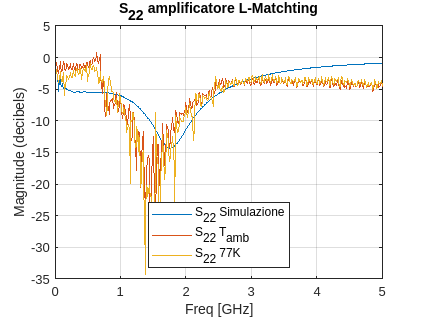


figure,plot(LNA,'S22','dB');
title("S_{22} amplificatore L-Matchting")
hold on
plot(LNA_sper,'S22','dB');
plot(LNA_sper_77K,'S22','dB');
legend("S_{22} Simulazione" , "S_{22} T_{amb}" , "S_{22} 77K" , "Location" , "south")
hold off

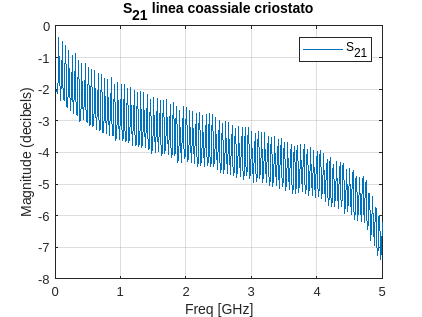





figure,plot(cavi,'S21','dB');
title("S_{21} linea coassiale criostato")
hold on

hold off